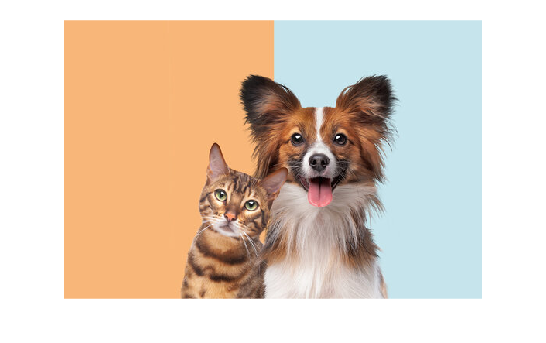

% Read the scene and object images
scene = imread('doggy.jpg');
object = imread('doggy.jpg');

% Convert images to grayscale
scene_gray = rgb2gray(scene);
object_gray = rgb2gray(object);

% Perform template matching using normalized cross-correlation
correlation_map = normxcorr2(object_gray, scene_gray);

% Find the peak correlation value and its location
[max_corr, max_index] = max(correlation_map(:));
[max_row, max_col] = ind2sub(size(correlation_map), max_index);

% Calculate the offset to adjust for padding added by normxcorr2
offset_row = size(object_gray, 1) - 1;
offset_col = size(object_gray, 2) - 1;

% Display the scene image with the detected object
figure;
imshow(scene);

hold on;
rectangle('Position', [max_col - offset_col, max_row - offset_row, size(object_gray, 2), size(object_gray, 1)], 'EdgeColor', 'r', 'LineWidth', 2);
title('Detected Object');

% Optionally, display the correlation map
figure;
surf(correlation_map);
shading flat;
title('Correlation Map');